optimizacion de 

# Low-carbon operation strategy of virtual power plant considering

# progressive demand response








clear all 
close all
clc
%%datos de los generadores
irrad=[0,0,0,0,0,0,86,293,563,949,1213,1135,1118,1108,863,766,546,227,6,0,0,0,0,0]*0.8;
wind=[141,156,133,154,140,127,101,174,276,323,356,351,296,251,275,226,200,138,111,149,201,229,177,165]*2;
G_tg=[750 723 721 850 922 863 841 750 880 798 895 875 1023 1052 999 933 9550 859 789 942 923 953 956 891]*0.8;
%%definimos el numero de periodos
T=24;
N_u=1;
Nload = 1;
%%parametros bateria 
capacity_b=1000; %%kWh
SOC_0 = 0.5; % Estado de carga inicial (opcional) = 0.5;
SOC_min=0.3;
SOC_max= 0.95;
cha_dis_limits= 300;
cha_dis_eff= 0.9;
%%%%%%%%%%%%%%%%%%

%%%% parametros trubina de gas %%

a=[0.008 0.008];    %%Fuel cost factor a
b=[0.04  0.04] ;    %%Fuel cost factor b
c=[42  42];         %%Fuel cost facto c
C_Gs=[308 340];        %%star-up cost(yuan)  
C_Gt=[248 260];        %%shutdown cost(yuan)
PGi__max=[800 1000];       %%the upper limit of output(kW)
PGi__min=[400 300];        %%the lower limit of output(kW)
Pci=[400 500];       %%climbing power(kW)

lambda_Gi= 0.76; %% kg/kWh emision de carbono de referencia por unidad de electricidad


%%variblaes costos de operacion y mantenimiento de generadores eolico y
%%fotovoltaico
Swind= 0.52;
Ssol= 0.72;
Ssto= 0.5;

%%variable de precio de veenta y compra de electricidad de la red electrica
C_buy= [0.30 0.30 0.30 0.30 0.30 0.30 0.61 0.86 0.86 0.86 0.86 0.61 0.61 0.86 0.86 0.86 0.86 0.86 0.61 0.61 0.61 0.30 0.30 0.3];
C_sell=[0.26 0.26 0.26 0.26 0.26 0.26 0.50 0.68 0.68 0.68 0.68 0.50 0.50 0.68 0.68 0.68 0.68 0.68 0.50 0.50 0.50 0.26 0.26 0.26];

%%precio de incentivo en la respuesta a la demanda
p_e_sub = [0.25 0.25 0.25 0.25 0.25 0.25 0.25 0.25 0.53 0.95 0.95  0.53 0.53 0.53 0.53 0.53 0.95 0.95 0.95 0.95 0.95 0.25 0.25 0.25  ];

%%variables de decisión
P_w = wind';
P_sol = irrad';
P_G = sdpvar(T, N_u,'full'); % Potencia generada por unidades térmicas
P_buy = sdpvar(T,1);  % Potencia
P_sell= sdpvar(T,1);
Pload_DRi=[676,683,664,662,677,658,604,1204,1745,1937,2162,2027,1731,1633,2022,2220,2296,2349,2149,1728,967,743,632,600]*0.25; % Datos de carga para cada hora del día

Pload_DR = sum(Pload_DRi, 1); % Sumar sobre los usuarios para cada tiempo.
Pnet = sdpvar(T, 1); % Potencia intercambiada con la red
Pbat = sdpvar(T, 1); % Potencia de salida de la batería
Pcha = sdpvar(T, 1); % Potencia de carga de la batería en cada intervalo de tiempo
Pdis = sdpvar(T, 1); % Potencia de descarga de la batería en cada intervalo de tiempo
Ebat = sdpvar(T, 1); % Carga de la batería
%%variables Binarias 

delta_Gs = binvar(T,N_u);
delta_Gt = binvar(T,N_u);
delta_Gr = binvar(T,N_u); % Variables binarias para estado (encendido/apagado)

delta_bs = binvar(T, 1); % Variable booleana para compra/venta de electricidad
delta_cha = binvar(T, 1); % Variable booleana para cargar la batería
delta_dis = binvar(T, 1); % Variable booleana para descargar la batería
delta_sta = binvar(T, 1); % 1 si la batería está inactiva, 0 de lo contrario

%%funcion de costos
%%la funcion de costos primero tiene como objetivo minimizar los 
%% costos operativos y de mantenimiento de los generadores fotovoltaico y eolico.
%% costos operativos de la turbina de gas
%% costos por compra y la venta de electricidad
%% costos por emision de carbono
%% costos de respuesta a la demanda


%% cada parte de la ecuacion tiene su equivalente
C_op = sum(Swind*P_w + Ssol*P_sol + Ssto * Pdis);
C_th = sum(sum(a(1)* P_G.^2 + b(1)* P_G + c(1) + delta_Gs* C_Gs(1) + delta_Gt*C_Gt(1)));
C_bs = sum(C_buy*P_buy + C_sell*P_sell);

% Emisiones de carbono y biomasa
beta_et_j = [0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305];
EG_c = sum(sum(beta_et_j* P_G));
EG_b = sum(sum(lambda_Gi* P_G));
% Costo de emisiones
lambda_E=30; 
C_ce = lambda_E * EG_c - lambda_E * EG_b;

nu = 0.5 * ones(1, T); % Incentivo o penalización fija para cada intervalo de tiempo [1 x T]
lambda_Ei = 1 * ones(1, T); % Coeficiente de DR fijo para cada intervalo de tiempo [1 x T]
%Pload_DRi =  sdpvar(Nload,T);
C_DR = sum(sum(p_e_sub.* Pload_DR + nu./lambda_Ei));


FminCvpp  =  C_ce +    + C_th +C_bs + C_op + C_DR; % +  ;

Most likely you meant to write a + b, but you wrote a +b
This can easily lead to bugs, as [a +b] is a vector with two elements
If you really want to use unitary plus, you will have to edit sdpvar/uplus
and delete this message


    Restricciones

constraints=[];


## Restricción de la turbina de gas.


% Restricciones para generadores térmicos
for t = 1:T
    for i = 1:N_u
        % Restricciones de potencia mínima y máxima con variables binarias
        constraints = [constraints, ...
            (delta_Gr(t, i) * PGi__min(i) <= P_G(t, i)) <= delta_Gr(t, i) * PGi__max(i)];
    end
end

%% Restricciones de rampa de potencia
for t = 1:T-1 % T-1 porque estamos considerando PGi(t+1)
    for i = 1:N_u
        % Restricción de cambio de potencia entre periodos consecutivos
        constraints = [constraints, ...
            -Pci(i) <= P_G(t+1, i) - P_G(t, i) <= Pci(i)];
    end
end

% Restricción de estado de generadores térmicos (no pueden estar encendidos y apagados simultáneamente)
for t = 1:T
    for i = 1:N_u
        constraints = [constraints, delta_Gs(t, i) + delta_Gt(t, i) <= 1];
    end
end

% Restricción de cambio de estado
delta_Gr_diff = sdpvar(T-1, N_u); % Diferencia de estado de encendido/apagado

% Calcular la diferencia de estado de encendido para cada generador y período
for t = 1:T-1
    for i = 1:N_u
        delta_Gr_diff(t, i) = delta_Gr(t+1, i) - delta_Gr(t, i);
    end
end

%% Restricción que asegura que el número total de cambios de estado no exceda el número de cambios posibles
sum_delta_Gdiff= sum(sum(delta_Gs - delta_Gt));

sum_delta_Gr_diff = sum(sum(delta_Gr_diff));



constraints = [constraints, sum_delta_Gr_diff <= sum_delta_Gdiff];



## restricciones de balance de potencia



% Añadir la restricción de balance de potencia para cada período de tiempo
Pload=[676,683,664,662,677,658,604,1204,1745,1937,2162,2027,1731,1633,2022,2220,2296,2349,2149,1728,967,743,632,600]; % Datos de carga para cada hora del día
for t = 1:T
    constraints = [constraints, ...
        Pnet(t) + wind(t) + irrad(t) + sum(P_G(t, :))  == Pload(t) + Pbat(t) ];
end


## restricciones de compra y venta de electricidad de la VPP


Ppower = 300;           % Límite de potencia de intercambio
% Relación entre Pnet, Pbuy, Psell y delta_bs
%constraints = [constraints, Pnet == delta_bs .* P_buy + (1 - delta_bs) .* P_sell];
% Introduce variables auxiliares
Pbuy_aux = sdpvar(T, 1);
Psell_aux = sdpvar(T, 1);

constraints = [constraints, Pnet == Pbuy_aux + Psell_aux];
constraints = [constraints, Pbuy_aux <= delta_bs * Ppower, Psell_aux <= (1 - delta_bs) * Ppower];
constraints = [constraints, Pbuy_aux >= 0, Psell_aux <= 0];


% Límite de Pnet
constraints = [constraints, (-Ppower <= Pnet) <= Ppower];

% Límite de Pbuy
constraints = [constraints, (0 <= P_buy) <= Ppower];

% Límite de Psell
constraints = [constraints, (-Ppower <= P_sell) <= 0];


## restricciones de las baterias

Pcs=600;
% Definir las restricciones de la batería
%constraints = [constraints, (-Pcs <= Pbat) <= Pcs];


% Pcha_aux = sdpvar(T, 1);
% Pdis_aux = sdpvar(T, 1);
% 
% constraints = [constraints, Pbat == Pcha_aux + Pdis_aux];
% constraints = [constraints, Pcha_aux <= delta_cha * Pcs, Pdis_aux <= (0 - delta_dis) * Pcs];
% constraints = [constraints, Pcha_aux >= 0, Pdis_aux <= 0];



% Límites de Pbat (potencia de la batería)
% optimize(constraints);
% 

% Límites de carga y descarga
% constraints = [constraints,( 0 <= Pcha )<= Pcs];
% constraints = [constraints, -Pcs <= Pdis <= 0];
% 
% 
% % Condiciones adicionales para asegurar que Pcha y Pdis se usan correctamente
% constraints = [constraints, implies(delta_cha, Pbat >= 0)];
% constraints = [constraints, implies(delta_dis, Pbat <= 0)];
% 
% %%restricciones del estado de la bateria
% % Restricción 1: La batería no puede estar cargando o descargando si está inactiva
% %constraints = [constraints, delta_sta .* (Pbat + Pdis + Pcha) == 0];
% % Restricción 1: La batería no puede cargar o descargar si está inactiva
% constraints = [constraints, Pbat + Pdis + Pcha <= delta_sta * (Pcs + Pcs + Pcs)];
% 
% % Restricción 2: La batería debe estar en uno de los tres estados (cargando, descargando, o inactiva)
% constraints = [constraints, delta_sta + delta_cha + delta_dis == 1];
% 
% % Restricción 2: La batería debe estar en uno de los tres estados
% constraints = [constraints, delta_sta + delta_dis + delta_cha == 1];


% Restricciones de batería

    % Restricciones de carga y descarga
    constraints = [constraints,... 
        -Pcs <= Pbat(t) <= Pcs,...
        Pbat(t) == Pcha(t) - Pdis(t), ... % Definición de la salida de la batería
        0 <= Pcha(t) <= Pcs * delta_cha(t), ... % Límite de carga controlado por delta_cha
        0 <= -Pdis(t) <= Pcs * delta_dis(t), ... % Límite de descarga controlado por delta_dis
         ... % Límite de la salida de la batería
        delta_cha(t) + delta_dis(t) + delta_sta(t) == 1]%, ... % Una sola operación a la vez

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|     ID|                     Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|     #1|    Element-wise inequality 2x1|            1 to 800|
|     #2|    Element-wise inequality 2x1|            1 to 800|
|     #3|    Element-wise inequality 2x1|            1 to 800|
|     #4|    Element-wise inequality 2x1|            1 to 800|
|     #5|    Element-wise inequality 2x1|            1 to 800|
|     #6|    Element-wise inequality 2x1|            1 to 800|
|     #7|    Element-wise inequality 2x1|            1 to 800|
|     #8|    Element-wise inequality 2x1|            1 to 800|
|     #9|    Element-wise inequality 2x1|            1 to 800|
|    #10|    Element-wise inequality 2x1|            1 to 800|
|    #11|    Element-wise inequality 2x1|            1 to 800|
|    #12|    Element-wise inequality 2x1|            1 to 800|
|    #13|    Element-wise inequality 2x1|            1 

        %delta_sta(t) * (Pbat(t) + Pdis(t) + Pcha(t)) == 0]; % Condición de estado inactivo
y = sdpvar(T, 1);
    M = 1; % Número suficientemente grande
    constraints = [constraints, ...
               y(t) <= M * delta_sta(t), ...
               y(t) >= -M * delta_sta(t), ...
               y(t) <= Pbat(t) + Pdis(t) + Pcha(t) - M * (1 - delta_sta(t)), ...
               y(t) >= Pbat(t) + Pdis(t) + Pcha(t) + M * (1 - delta_sta(t))];

## estados del SOC de la bateria

Emax = 1000; % Capacidad máxima de la batería en kWh
eta_cha = 0.9; % Eficiencia de carga
eta_dis = 0.9; % Eficiencia de descarga
% Inicialización de la carga de la batería
constraints = [constraints,Ebat(1) == SOC_0 * Emax]; % Estado de carga inicial

% Restricción dinámica de carga de la batería
for t = 2:T
    constraints = [constraints, Ebat(t) == Ebat(t-1) + Pcha(t) - Pdis(t)];
end

% Restricción de energía disponible
constraints = [constraints, ...
    Emax * (SOC_min - SOC_0) <= sum(Pcha .* eta_cha - Pdis .* eta_dis) <= Emax * (SOC_max - SOC_0)];

% Restricción de carga y descarga nula
constraints = [constraints, sum(Pcha + Pdis) == 0];


##  Restricción de incentivos DR.

Fmin = 0.1; % Valor mínimo de fluctuación
Fmax = 0.8; % Valor máximo de fluctuación
chi = 1; % Valor máximo del coeficiente de respuesta a la demanda

% Variables de decisión
lambda_x = sdpvar(T, 1); % Coeficiente de respuesta a la demanda
W_DR = 0.1; % Factor de ponderación para cada usuario
Pload_i =[0.5, 0.4, 0.4, 0.3, 0.3, 0.6, 1.2, 1.5, 1.0, 0.8, 0.7, 0.6, ...
                    0.5, 0.5, 0.4, 0.6, 0.7, 1.2, 1.8, 2.0, 1.5, 1.0, 0.8, 0.6]; % kWh

% Coeficientes de respuesta a la demanda
lambda_min_x = 0.2; % Ejemplo de valor mínimo
lambda_max_x = 0.5; % Ejemplo de valor máximo

% Restricción de fluctuación
F_x = (lambda_max_x - lambda_min_x) / lambda_max_x;
constraints = [constraints, Fmin <= F_x, F_x <= Fmax];

% Restricción de capacidad de respuesta
%constraints = [constraints, (sum(lambda_min_x * W_DR * Pload_i) <= lambda_x.* W_DR * Pload_i )<= sum(lambda_max_x * W_DR * Pload_i)];


% Restricción del coeficiente de respuesta
constraints = [constraints, (0 <= lambda_x) <= chi];
% optimize(constraints)

## Resolver el problema

options = sdpsettings('verbose', 0, 'solver', 'Cplex'); % Usa el solucionador de tu elección

sol = optimize(constraints,FminCvpp,options);
if sol.problem == 0
    % Si no hay errores
    fprintf('Optimización completada con éxito.\n');
    P_G_opt = value(P_G);
    P_w_opt = value(P_w);
    P_sol_opt = value(P_sol);
    % Aquí puedes agregar más resultados
else
    disp('Problema en la optimización:');
    disp(yalmiperror(sol.problem));
end

Optimización completada con éxito.


## valores


% Obtén los valores de las variables de decisión
P_w_val = value(P_w);
P_sol_val = value(P_sol);
P_G_val = value(P_G);
P_buy_val = value(P_buy);
P_sell_val = value(P_sell);
Pload_DRi_val = value(Pload_DRi);
Pload_DR_val = value(Pload_DR);
Pnet_val = value(Pnet);
Pbat_val = value(Pbat);
Pcha_val = value(Pcha);
Pdis_val = value(Pdis);
Ebat_val = value(Ebat);
delta_Gs_val = value(delta_Gs);
delta_Gt_val = value(delta_Gt);
delta_Gr_val = value(delta_Gr);
delta_bs_val = value(delta_bs);
delta_cha_val = value(delta_cha);
delta_dis_val = value(delta_dis);
delta_sta_val = value(delta_sta);
lambda_x_val = value(lambda_x);
W_DR_val = value(W_DR);
Pload_i_val = value(Pload_i);

% Muestra los valores
disp('Valores de las variables de decisión:');

Valores de las variables de decisión:


disp('P_w:');

P_w:


disp(P_w_val);

   282
   312
   266
   308
   280
   254
   202
   348
   552
   646
   712
   702
   592
   502
   550
   452
   400
   276
   222
   298
   402
   458
   354
   330



disp('P_sol:');

P_sol:


disp(P_sol_val);

         0
         0
         0
         0
         0
         0
   68.8000
  234.4000
  450.4000
  759.2000
  970.4000
  908.0000
  894.4000
  886.4000
  690.4000
  612.8000
  436.8000
  181.6000
    4.8000
         0
         0
         0
         0
         0



disp('P_G:');

P_G:


disp(P_G_val);

  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  800.0000
  570.0000



disp('P_buy:');

P_buy:


disp(P_buy_val);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



disp('P_sell:');

P_sell:


disp(P_sell_val);

  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300
  -300



disp('Pload_DRi:');

Pload_DRi:


disp(Pload_DRi_val);

  Columns 1 through 16

  169.0000  170.7500  166.0000  165.5000  169.2500  164.5000  151.0000  301.0000  436.2500  484.2500  540.5000  506.7500  432.7500  408.2500  505.5000  555.0000

  Columns 17 through 24

  574.0000  587.2500  537.2500  432.0000  241.7500  185.7500  158.0000  150.0000



disp('Pload_DR:');

Pload_DR:


disp(Pload_DR_val);

  Columns 1 through 16

  169.0000  170.7500  166.0000  165.5000  169.2500  164.5000  151.0000  301.0000  436.2500  484.2500  540.5000  506.7500  432.7500  408.2500  505.5000  555.0000

  Columns 17 through 24

  574.0000  587.2500  537.2500  432.0000  241.7500  185.7500  158.0000  150.0000



disp('Pnet:');

Pnet:


disp(Pnet_val);

  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
  300.0000
 -300.0000



disp('Pbat:');

Pbat:


disp(Pbat_val);

  706.0000
  729.0000
  702.0000
  746.0000
  703.0000
  696.0000
  766.8000
  478.4000
  357.4000
  568.2000
  620.4000
  683.0000
  855.4000
  855.4000
  318.4000
  -55.2000
 -359.2000
 -791.4000
 -822.2000
 -330.0000
  535.0000
  815.0000
  822.0000
   -0.0000



disp('Pcha:');

Pcha:


disp(Pcha_val);

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
  250.0000
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



disp('Pdis:');

Pdis:


disp(Pdis_val);

         0
         0
 -250.0000
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



disp('Ebat:');

Ebat:


disp(Ebat_val);

         500
         500
         750
         750
         750
         750
         750
         750
         750
         750
         750
        1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000



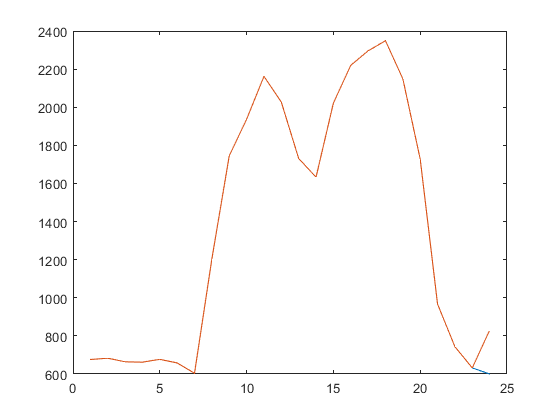



% %constraints = [constraints, Pbat == delta_cha .* Pcha + delta_dis .* Pdis];
% for t = 1:T
%     % Si la batería está cargando
%     constraints = [constraints, implies(delta_cha(t) == 1, Pbat(t) == Pcha(t))];
%     constraints = [constraints, implies(delta_cha(t) == 1, Pbat(t) >= 0)];
%     
%     % Si la batería está descargando
%     constraints = [constraints, implies(delta_dis(t) == 1, Pbat(t) == Pdis(t))];
%     constraints = [constraints, implies(delta_dis(t) == 1, Pbat(t) <= 0)];
%     
%     % Solo una operación activa a la vez
%     constraints = [constraints, delta_cha(t) + delta_dis(t) <= 1];
% end


plot(Pload)
hold on 
plot(P_G_val(1)+P_w_val+P_sol_val -Pbat_val +Pnet_val)